**Practice 5:** Suppose the grades of 6 students are given as $[17, 15, 19, 12, 14, 20]$, and their names are stored as `{'Ali','Sara','Reza','Mina','Hamed','Zahra'}`. Draw a bar chart and use a special color (e.g., gold) for the grade 20.

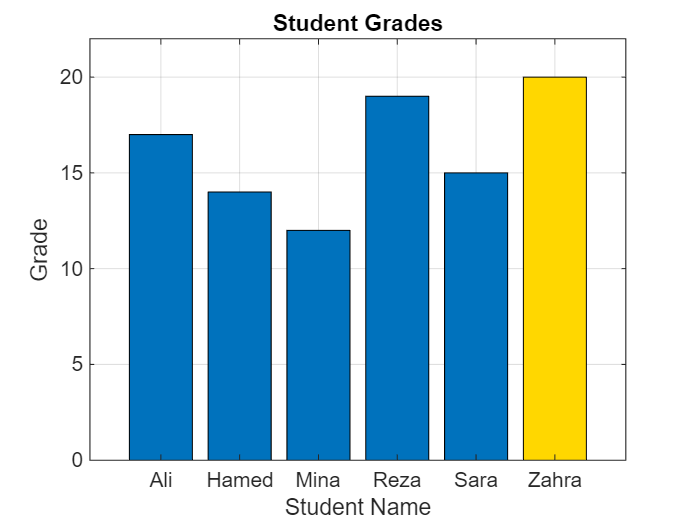

grades = [17, 15, 19, 12, 14, 20];
names = {'Ali','Sara','Reza','Mina','Hamed','Zahra'};

studentNames = categorical(names);

numStudents = numel(grades);
defaultColor = [0 0.4470 0.7410];
specialColor = [1, 215/255, 0];
specialGrade = 20;

barColors = repmat(defaultColor, numStudents, 1);
specialIndex = find(grades == specialGrade);
barColors(specialIndex, :) = repmat(specialColor, numel(specialIndex), 1);

b = bar(studentNames, grades);
b.FaceColor = 'flat'; 
b.CData = barColors;
title('Student Grades');
xlabel('Student Name');
ylabel('Grade');
ylim([0, max(grades) + 2]);
grid on;

**Practice 6:** The hyperbolic function is defined as follows:


$$y(x) = a . \cosh(\frac{x}{a})$$


where $\cosh$ is a hyperbolic function. For $a = 1$, plot the curve in the range $[-5,5]$ and use a color of your choice for the plot.

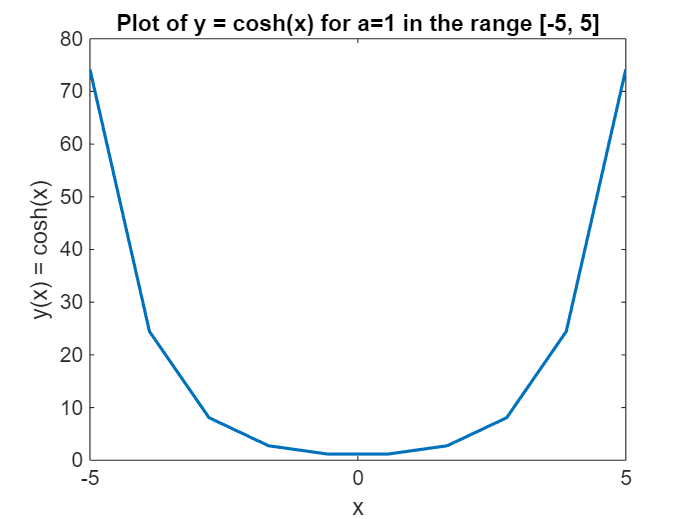

a = 1;
x = linspace(-5, 5, 10);
y = @(x) a * cosh(x / a);

plot(x, y(x), 'LineWidth', 1.5);
xlabel('x');
ylabel('y(x) = cosh(x)');
title('Plot of y = cosh(x) for a=1 in the range [-5, 5]');

**Practice 7:** Generate random three-dimensional data and create a 3D scatter plot. Then, color the data points with different colors based on one of the components.

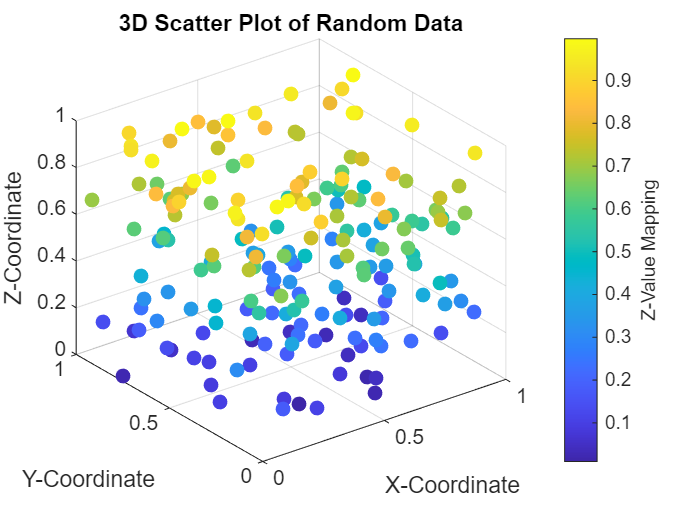

x = rand(200, 1);
y = rand(200, 1);
z = rand(200, 1);

markerSize = 50;
colorData = z;
scatterHandle = scatter3(x, y, z, markerSize, colorData, 'filled');

xlabel('X-Coordinate');
ylabel('Y-Coordinate');
zlabel('Z-Coordinate');

title('3D Scatter Plot of Random Data');

cb = colorbar;
ylabel(cb, 'Z-Value Mapping');

grid on;

**Practice 8:** Write a while loop that sums odd numbers and stops when the sum reaches or exceeds $1000$. Then, display the number of odd numbers that have been summed.

s = 0;
i = 1;
counter = 0;

while s < 1000
    if mod(i, 2) ~= 0
        s = s + i;
        counter = counter + 1;
    end

    i = i + 1;
end

fprintf("Sum: %d\n", s);

Sum: 1024


fprintf("Number of odd numbers: %d", counter);

Number of odd numbers: 32

**Practice 9:** The Fibonacci sequence is defined as follows:


$$\begin{cases}
F(0) = 0 \\ 
F(1) = 1 \\ 
F(n) = F(n - 1) + F(n - 2) & \text{for } n \geq 2
\end{cases}$$


Calculate the Fibonacci sequence up to $n = 15$ using a for loop and display it.

n = 15;
fib = zeros(1, n);
fib(1) = 0;
fib(2) = 1;

for i = 3:n
    fib(i) = fib(i - 1) + fib(i - 2);
end

disp("Fibonacci sequence up to 15:")

Fibonacci sequence up to 15:


disp(fib);

     0     1     1     2     3     5     8    13    21    34    55    89   144   233   377



**Practice 10:** Merge Sort is a divide-and-conquer sorting algorithm that first divides the array into smaller sub-arrays and then recursively sorts these sub-arrays. Finally, it merges them together to form the final sorted array.

Write a function that sorts an array using the Merge Sort algorithm.

`A = [38, 27, 43, 3, 9, 82, 10];`

function sortedA = mergeSort(A)
    n = numel(A);
    if n <= 1
        sortedA = A;
        return;
    end

    mid = floor(n / 2);
    left = A(1:mid);
    right = A(mid+1:n);

    sortedLeft = mergeSort(left);
    sortedRight = mergeSort(right);

    sortedA = merge(sortedLeft, sortedRight);
end

function result = merge(left, right)
    nLeft = numel(left);
    nRight = numel(right);
    result = zeros(1, nLeft + nRight);
    i = 1;
    j = 1;
    k = 1;

    while i <= nLeft && j <= nRight
        if left(i) <= right(j)
            result(k) = left(i);
            i = i + 1;
        else
            result(k) = right(j);
            j = j + 1;
        end
        k = k + 1;
    end

    while i <= nLeft
        result(k) = left(i);
        i = i + 1;
        k = k + 1;
    end

    while j <= nRight
        result(k) = right(j);
        j = j + 1;
        k = k + 1;
    end
end

A = [38, 27, 43, 3, 9, 82, 10];
sorted_A = mergeSort(A);
disp(sorted_A);

     3     9    10    27    38    43    82

